Filtern von Digitalen Bildern

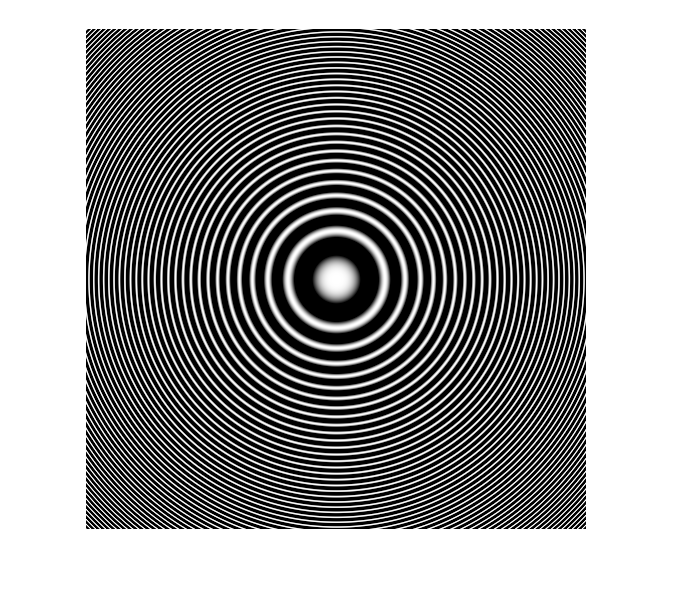

mI = im2double(imread('chirp.png'));
figure, imshow(mI)

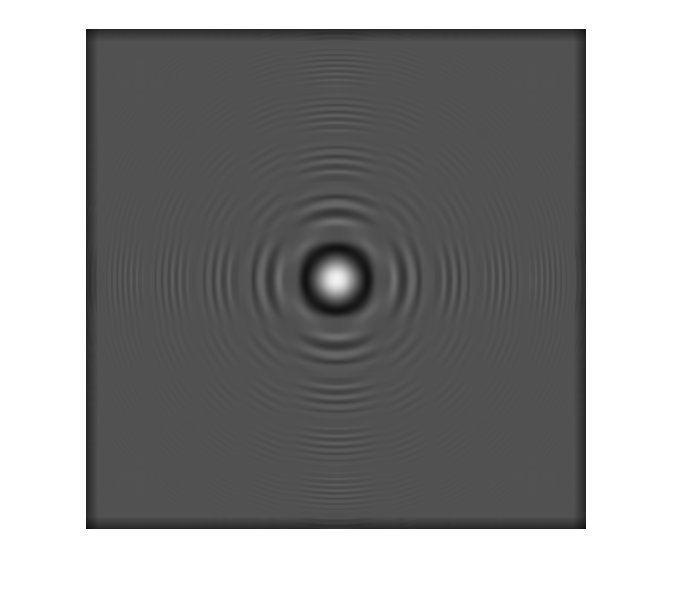

mH = ones(25);
mH = mH/sum(mH(:));
mI_lp = imfilter(mI, mH);
figure, imshow(mI_lp)

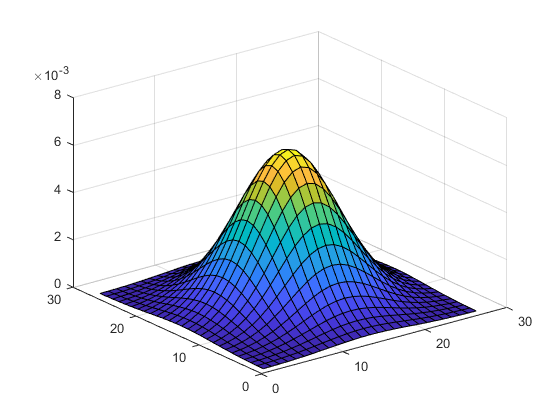


%Gausfilter
sigma = 5;
L = 2 * ceil(5/2 * sigma) + 1;
L2 = ceil(5/2 * sigma) + 1;

%vX = -L2:L2;

%1D-Gausfilter
%mH_Gaus = exp(-vX.^2/sigma^2);
%mH_Gaus = mH_Gaus/(sum(mH_Gaus));

%2D-Gausfilter
%vY = vX;
%[mX, mY] = meshgrid(vX, vY);
%mH_Gaus = exp(-(mX/sigma).^2).*exp(-(mY/sigma).^2);
%mH_Gaus = mH_Gaus/sum(mH_Gaus(:));
mH_Gaus = fspecial('gaussian', L, sigma);

figure, surf(mH_Gaus)

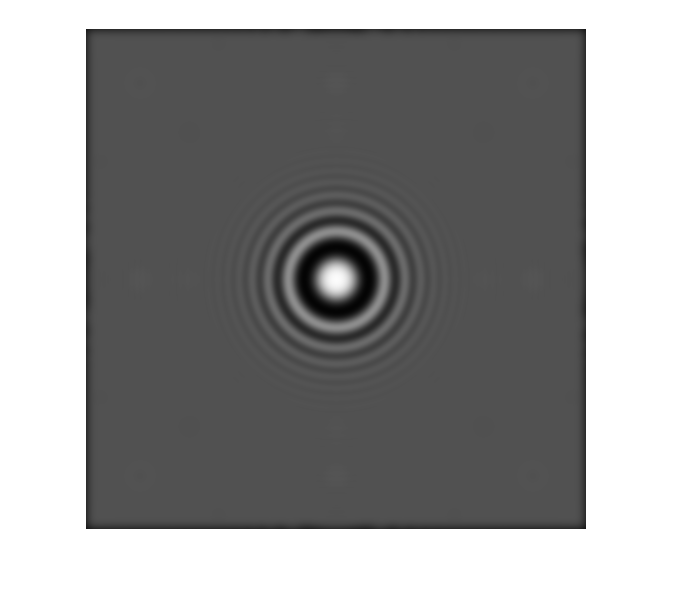


mH_Gaus_filter = imfilter(mI, mH_Gaus);
figure, imshow(mH_Gaus_filter)